clc;
clf;
close all;
clear all;
%y(n)=conv(x1,x2) - for verification purposes
%Initialization
x1=input('Enter first sequence: ');
x2=input('Enter second sequence: ');
n=length(x1);
m=length(x2);
l=n+m-1;
y=zeros(1,l);
for i=1:n
for k=1:m
y(i+k-1)=y(i+k-1)+x1(i)*x2(k);
end
end
disp(y);

     0     0     2     3     2



%Plotting
%Declaring X-axis for plotting
sam_point1=1:1:n;
sam_point2=1:1:m;
sam_point3=1:1:l;
tile=tiledlayout(2,2);
title(tile, 'Linear Convolution');
nexttile;
stem(sam_point1,x1);
title('x[n]');
xlabel('Samples');
ylabel('Amplitude');
grid on;
nexttile;
stem(sam_point2,x2);
title('h[n]');
xlabel('Samples');
ylabel('Amplitude');
grid on;
nexttile;
stem(sam_point3,y);
title('User-Built Function');
xlabel('Samples');
ylabel('Amplitude');
grid on;
y_conv=conv(x1,x2);
disp(y_conv);

     0     0     2     3     2



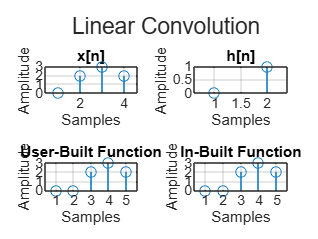

len_y_conv=length(y_conv);
sam_point4=1:1:len_y_conv;
nexttile;
stem(sam_point4,y_conv);
title('In-Built Function');
xlabel('Samples');
ylabel('Amplitude');
grid on;